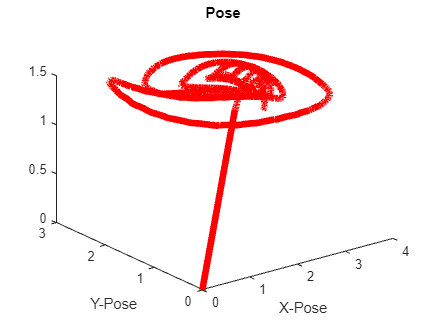

clear; % clears all var
clc; % clears command window
%data = load("third_successful.mat");
%data = load("fifth_successful.mat");
data = load("cw_elipse.mat");
ref = load("reference.mat");
ref_x = ref.C3(11,1:3620)-1.2;
ref_y = ref.C3(12,1:3620)-0.15;
ref_z = flip(ref.C3(13,1:3620));

%data = load("second_successful.mat");
% ccw_lower_limit = 1100; % 1430 600 
% ccw_upper_limit = 1410; % 1730 1000

ccw_lower_limit = 1; % 1430 600 
ccw_upper_limit = 2500; % 1730 1000

x_ccw = -1*transpose(data.test(ccw_lower_limit:ccw_upper_limit,5));
y_ccw = transpose(data.test(ccw_lower_limit:ccw_upper_limit,6));
z_ccw = transpose(data.test(ccw_lower_limit:ccw_upper_limit,7));
x_g_ccw = smoothdata(x_ccw,'gaussian',32);
y_g_ccw = smoothdata(y_ccw,'gaussian',32);
z_g_ccw = smoothdata(z_ccw,'gaussian',32);

% x_cw = -1*transpose(data.test(cw_lower_limit:cw_upper_limit,1));
% y_cw = transpose(data.test(cw_lower_limit:cw_upper_limit,2));
% z_cw = transpose(data.test(cw_lower_limit:cw_upper_limit,3));
% x_g_cw = smoothdata(x_cw,'gaussian',32);
% y_g_cw = smoothdata(y_cw,'gaussian',32);
% z_g_cw = smoothdata(z_cw,'gaussian',32);
% x_1 = transpose(data.test(1715:2120,1))-0.2;
% y_1 = transpose(data.test(1715:2120,2))+0.2;
% 
% 
% x_2 = transpose(data.test(1325:1730,1));
% y_2 = transpose(data.test(1325:1730,2));
% 
% 
% x_3 = transpose(data.test(1710:2115,1))-0.15;
% y_3 = transpose(data.test(1710:2115,2))+0.2;

% x_ult = (x_1 + x_2 + x_3)/3;
% y_ult = (y_1 + y_2 + y_3)/3;
% x_g = smoothdata(x_ult,'gaussian',10);
% y_g = smoothdata(y_ult,'gaussian',10);
% bod_rates = transpose(data.test(1:limit,3)); 
% motor = transpose(data.test(1:limit,4));
% motor = smoothdata(motor,'gaussian',1000);
% bod_rates_g = smoothdata(bod_rates,'gaussian',1000);
% heading = rad2deg(transpose(data.test(1:limit,5)));
% pitch = rad2deg(transpose(data.test(1:limit,6)));
% pitch = smoothdata(pitch,'gaussian',1000);
% 
% 
% 
% 
% 
% 
% plot(time,smoothedbod_roll,'Color','b','linewidth',5)
figure(1)

% plot(ref_x,ref_y,'Color','b','linewidth',5)
% xlabel('X-Pose Ref')
% ylabel('Y-Pose Ref')
% title('Ref Pose')
%axis equal

%hold on
plot3(x_ccw,y_ccw,z_ccw,'Color','r','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')
title('Pose ')

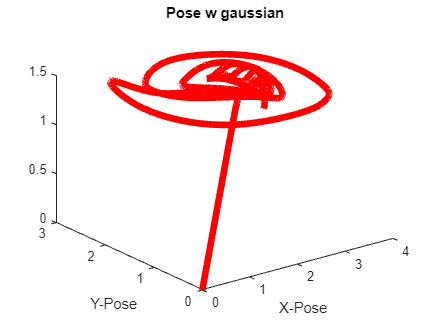

%axis equal
%hold off
% 
% hold on
% plot(x_2,y_2,'Color','r','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% 
% 
% plot(x_3,y_3,'Color','g','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% 
% 
% hold off 


plot3(x_g_ccw,y_g_ccw,z_g_ccw,'Color','r','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')
title('Pose w gaussian')

% title('comparison')



% plot3(ref_x, ref_y, ref_z, 'Color','r','LineWidth',2);
% xlabel('X-Pose')
% ylabel('Y-Pose')
% zlabel('Z-Pose')

% plot(x_ult,y_ult,'Color','g','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% 
% 
% plot(x_g,y_g,'Color','r','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% title('Pose w gaussian')
% % % title('comparison')
% hold on
% plot(ref_x,ref_y,'Color','b','linewidth',5)
% xlabel('X-Pose Ref')
% ylabel('Y-Pose Ref')
% title('Ref Pose')
% legend('actual',"ref");
% hold off

% plot(1:limit,bod_rates_g,'Color','b','linewidth',5)
% xlabel('Time')
% ylabel('Bod Rates')
% title('Rates vs index')
% plot(1:limit,motor,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('Motor')
% title('Motor vs index')
% plot(1:limit,heading,'Color','b','linewidth',5)
% xlabel('Time')
% ylabel('heading')
% title('Heading vs index')
% plot(1:limit,pitch,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('pitch')
% title('Pitch vs index')
